clc;
clear;
Tuning1 = load("Data/M6M5ID_Test1_actuation_uncompensated.mat");
Tuning1 = Tuning1.data;

% Search for testing times via force plate z readings:
FPz = Tuning1{3}.Values;

Start_times = [];
End_times = [];
valid = false;
for i =1:length(FPz.Data)
    if valid
        if FPz.Data(i)>-5
            End_times = [End_times, FPz.Time(i)]; % Chop off the robot being picked up
            valid = false;
        end    
    else
        if FPz.Data(i)<-30
            Start_times = [Start_times, FPz.Time(i)];% Chop off the robot being put down
            valid = true;
        end
    end
end
End_times(5) = End_times(5) -10; % Strange artifact at the end of final sample - something went wring with lifting off the force plate.

% Torques calculated via force plate forces using the jacobian, 

FPy = [];
FPz = [];
MRq = [];
MLq = [];
MRt_read = [];
MLt_read = [];
MRt_cmd = [];
MLt_cmd = [];
ts = 1000;
Start_times =int32(Start_times*ts);
End_times = int32(End_times*ts);



% Resamples
MR_q_resample = resample(Tuning1{5}.Values.q, Tuning1{1}.Values.Time);
ML_q_resample = resample(Tuning1{6}.Values.q, Tuning1{1}.Values.Time);
MR_t_resample = resample(Tuning1{5}.Values.t, Tuning1{1}.Values.Time);
ML_t_resample = resample(Tuning1{6}.Values.t, Tuning1{1}.Values.Time);
MR_t_cmd_resample = resample(Tuning1{9}.Values.tff, Tuning1{1}.Values.Time);
ML_t_cmd_resample = resample(Tuning1{8}.Values.tff, Tuning1{1}.Values.Time);
for i = 1:length(Start_times)
    % Force plate
    FPy = [FPy; Tuning1{2}.Values.Data(Start_times(i): End_times(i))];
    FPz = [FPz; Tuning1{3}.Values.Data(Start_times(i): End_times(i))];
    % Motor angles
    
    MRq = [MRq; MR_q_resample.Data(Start_times(i): End_times(i))];
    MLq = [MLq; ML_q_resample.Data(Start_times(i): End_times(i))];

    % Motor torques (cmd)
    
    MRt_cmd = [MRt_cmd; MR_t_cmd_resample.Data(Start_times(i): End_times(i))]; 
    MLt_cmd = [MLt_cmd; ML_t_cmd_resample.Data(Start_times(i): End_times(i))];
    
    % Motor torques (read)
   
    MRt_read = [MRt_read; MR_t_resample.Data(Start_times(i): End_times(i))];
    MLt_read = [MLt_read; ML_t_resample.Data(Start_times(i): End_times(i))];

end
clear MR_q_resample ML_q_resample MR_t_resample ML_t_resample MR_t_cmd_resample ML_t_cmd_resample


## Transfer force plate data into torques

% From the side of forces:
Fy_cmd = [];
Fz_cmd = [];
Fy_read = [];
Fz_read = [];
FP_tl = [];
FP_tr = [];
[J11, J12, J21, J22] = BalekaJacobianXY(MLq, MRq);
for i = 1:length(MLt_cmd)
    Jxy = [J11(i), J12(i); J21(i), J22(i)];
    JTxy = Jxy';

    FP_t = JTxy*[FPy(i); FPz(i)];
    FP_tl = [FP_tl, FP_t(1)];
    FP_tr = [FP_tr, FP_t(2)];

    % F_cmd = JTxy\[MLt_cmd(i); MRt_cmd(i)];
    % Fy_cmd = [Fy_cmd; -F_cmd(1)];
    % Fz_cmd = [Fz_cmd; -F_cmd(2)];
    % 
    % F_read = JTxy\[MLt_read(i)*9*0.198; MRt_read(i)*9*0.198];
    % Fy_read = [Fy_read; -F_read(1)];
    % Fz_read = [Fz_read; -F_read(2)];
end
clear F_cmd F_read i J11 J12 J22 J21 times ts JTxy Jxy


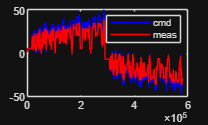

x = [FP_tl, FP_tr];
y = [MLt_cmd; MRt_cmd]';
%Motor command compensation
plot(y, 'b');
hold on
plot(x, 'r');
legend("cmd", "meas")
hold off

% Line of best fit

m1L = FP_tl(:)\MLt_cmd(:)

m1L = 1.2249

RsqL = corrcoef(FP_tl, MLt_cmd).^2

RsqL =     1.0000    0.9804
    0.9804    1.0000


percentErrorTorquesL = mean(abs((MLt_cmd' - FP_tl)./FP_tl)*100)

percentErrorTorquesL = 20.4822

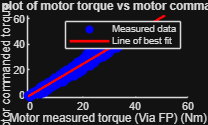

% [coeff, Sc] = polyfit(x,y, 1);
xFitL = linspace(min(FP_tl), max(MLt_cmd), 1000);
yFitL = polyval([m1L 0], xFitL);


scatter(FP_tl, MLt_cmd, 'b','filled')
hold on
plot(xFitL, yFitL, 'r-', LineWidth=2)
title("Scatter plot of motor torque vs motor command LEFT");
ylabel("Motor commanded torque (Nm)");
xlabel("Motor measured torque (Via FP) (Nm)");
legend("Measured data", "Line of best fit")
hold off


m1R = FP_tr(:)\MRt_cmd(:)

m1R = 1.1986

RsqR = corrcoef(FP_tr, MRt_cmd).^2

RsqR =     1.0000    0.9785
    0.9785    1.0000


percentErrorTorquesR = mean(abs((MRt_cmd' - FP_tr)./FP_tr)*100)

percentErrorTorquesR = 65.2765

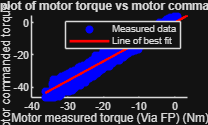

% [coeff, Sc] = polyfit(x,y, 1);
xFitR = linspace(min(FP_tr), max(MRt_cmd), 1000);
yFitR = polyval([m1R 0], xFitR);


scatter(FP_tr, MRt_cmd, 'b','filled')
hold on
plot(xFitR, yFitR, 'r-', LineWidth=2)
title("Scatter plot of motor torque vs motor command RIGHT");
ylabel("Motor commanded torque (Nm)");
xlabel("Motor measured torque (Via FP) (Nm)");
legend("Measured data", "Line of best fit")
hold off

% m2 = coeff(1)
% c2 = coeff(2)
% %where line of best fit is y=mx +c
% Sc

% t1 = 9000;
% t2 = 11000;
% linwidth = 1.5;
% t = linspace(0, length(FPz(t1:t2))/1000, length(FPz(t1:t2)));
% plot(t, Fz_cmd(t1: t2), LineWidth=linwidth, LineStyle='-', Color='#DDAA33')
% hold on
% plot(t, FPz(t1:t2), LineWidth=linwidth, LineStyle='--', Color='#BB5566')
% plot(t, Fz_read(t1:t2), LineWidth=linwidth, LineStyle='--', Color='#004488' )
% legend('Leg commanded force', 'Force plate measurement', 'Leg proprioception');
% title('Original (uncompensated) Vertical forces')
% 
% xlabel("Time (s)")
% ylabel("Force (N)")
% hold off